# LC Tank Circuit

## Introduction

When a capacitor get discharged through an inductor it causes oscilatory displacement of charges between the conductor plates of the capaciotr. Such type of circuit is called as LC tank circuit or LC parallel circuit. One such circuit is shown in following figure. In this circuit if we connect the oscilloscope across the inductor and close the switch, oscilloscope will show the sinusoidal voltage plot. The frequency of the sinusoidal voltage plot will be 

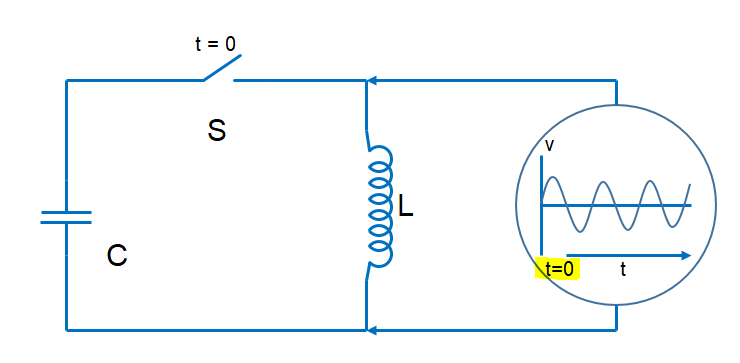

#### Using Simscape the LC tank model created as shown below

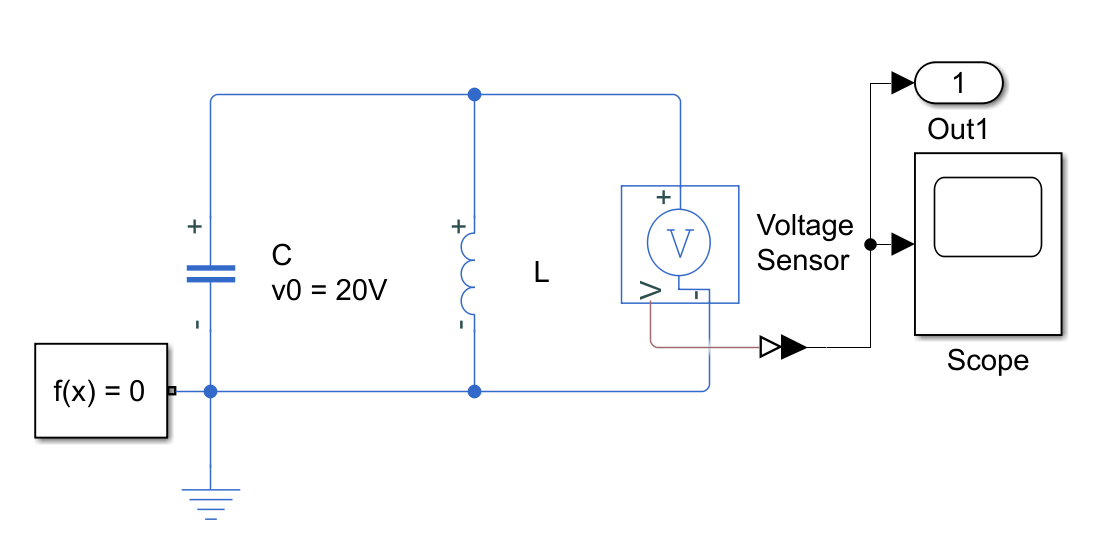

## Interactive Simulation

Form here you can change the values of L and C and can observe changes in frequency

### for sample value of L = 100 mH and C = 5000 uF, T wii be 141 ms

clc;
clear;

C = 5000;
L = 120;

T = 2*pi* sqrt((L/1000)*(C/1000000));
fprintf("T =  %.2f",T);

T =  0.15

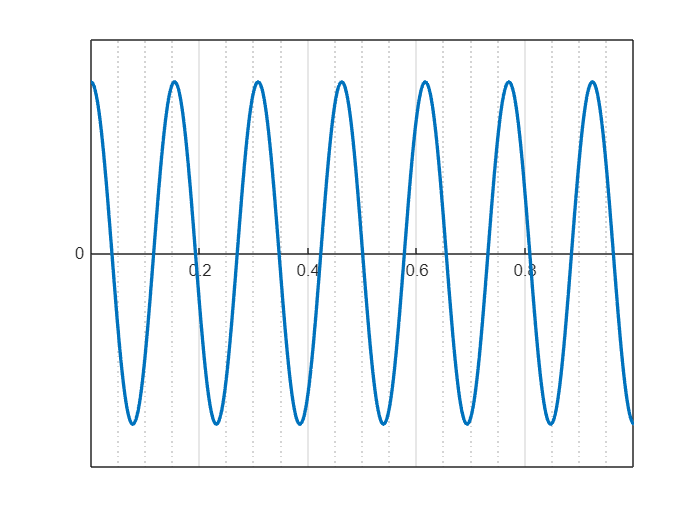

sim("LC_TankCkt.slx");
t = ans.get('tout');
yout = ans.get("yout");
dataset = yout.get("Vout");
signal = dataset.Values.Data;
signalForPlot = signal(:);
plot(t,signalForPlot,'LineWidth',2.0);
xlim([0 1]);
ylim([-25 25]);
ax = gca; % current axes
ax.XAxisLocation = "origin";
ax.YTick = [0];
ax.XGrid = 'on';
ax.XMinorGrid = 'on';

**NOTE: This code uses Dataset to export data from simulink to matlab script**